1) Wyznaczanie rozkładu LU

    a) Test metod

A=[5,3,2;1,2,0;3,0,4]

A =      5     3     2
     1     2     0
     3     0     4



[L U]=gauss(A)

L =     1.0000         0         0
    0.2000    1.0000         0
    0.6000   -1.2857    1.0000


U =     5.0000    3.0000    2.0000
         0    1.4000   -0.4000
         0         0    2.2857


LU=L*U

LU =     5.0000    3.0000    2.0000
    1.0000    2.0000         0
    3.0000   -0.0000    4.0000


[L U]=dolittle(A)

L =     1.0000         0         0
    0.2000    1.0000         0
    0.6000   -1.2857    1.0000


U =     5.0000    3.0000    2.0000
         0    1.4000   -0.4000
         0         0    2.2857


LU=L*U

LU =     5.0000    3.0000    2.0000
    1.0000    2.0000         0
    3.0000         0    4.0000


[L U P]=LUP(A)

L =     1.0000         0         0
    0.6000    1.0000         0
    0.2000   -0.7778    1.0000


U =     5.0000    3.0000    2.0000
         0   -1.8000    2.8000
         0         0    1.7778


P =      1     0     0
     0     0     1
     0     1     0


LU=L*U

LU =      5     3     2
     3     0     4
     1     2     0


PA=P*A

PA =      5     3     2
     3     0     4
     1     2     0


    b) Porównanie szybkości metod - 1000 losowych macierzy

iterations=1000;
tic
for i=1:iterations
A=rand(4)*10;
[L,U]=dolittle(A);
end
czasDolittle=toc

czasDolittle = 0.0058


tic
for i=1:iterations
A=rand(4)*10;
[L,U]=gauss(A);
end
czasGauss=toc

czasGauss = 0.0140

    c) Czas obliczania LU obiema metodami dla różnych rozmiarów macierzy A

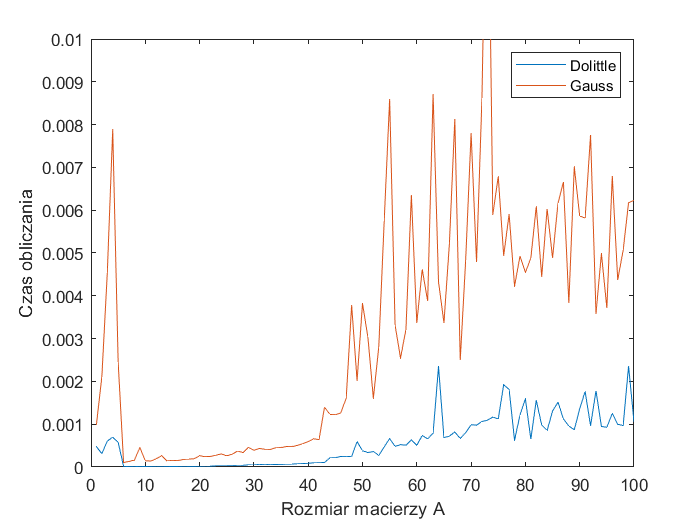

iterations=100;
tDoLittle=zeros(1,iterations);
tGauss=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[L,U]=dolittle(A);
tDoLittle(i)=toc;

tic
[L,U]=gauss(A);
tGauss(i)=toc;
end

plot(x,tDoLittle);
hold on;
plot(x,tGauss);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("Dolittle","Gauss")
ylim([0,0.01]);
hold off;

2) Badanie wpływu zaburzeń

c=2;
n=4;

x_dokladne=zeros(n,c);
x_A_element=zeros(n,c);
x_A_kolumna=zeros(n,c);
x_A_caly=zeros(n,c);
x_b_caly=zeros(n,c);

delta=rand(1,1)*10;


for i=1:c
    [A,b,x]=tstcnd(4,i);
  
    x_dokladne(:,i)=x
    
    A_element=A;
    A_element(1,1)=A(1,1)+delta;
    x_A_element(:,i)=linsolve(A_element,b)
    
    A_kolumna=A;
    A_kolumna(:,1)=A(:,1)+delta;
    x_A_kolumna(:,i)=linsolve(A_kolumna,b)
    
    A_caly=A+delta;
    x_A_caly(:,i)=linsolve(A_caly,b)
    
    b_caly=b+delta; 
    x_b_caly(:,i)=linsolve(A,b_caly)
end

x_dokladne =     -5     0
     3     0
     7     0
     2     0


x_A_element =    -4.9999         0
    3.0002         0
    6.9999         0
    2.0000         0


x_A_kolumna =    -5.0000         0
    3.0001         0
    6.9997         0
    2.0002         0


x_A_caly =    -5.0000         0
    2.9999         0
    7.0005         0
    1.9997         0


x_b_caly =    -5.0000         0
    3.0000         0
    6.9999         0
    2.0000         0


x_dokladne =     -5     1
     3    -1
     7     4
     2    -4


x_A_element =    -4.9999    1.0000
    3.0002   -0.9999
    6.9999    4.0000
    2.0000   -4.0000


x_A_kolumna =    -5.0000    1.0000
    3.0001   -0.9999
    6.9997    4.0000
    2.0002   -4.0000


x_A_caly =    -5.0000    1.0000
    2.9999   -1.0000
    7.0005    4.0000
    1.9997   -4.0000


x_b_caly =    -5.0000    1.0000
    3.0000   -1.0001
    6.9999    4.0000
    2.0000   -4.0000


3) Zastosowania rozkładu LU

    a)

Test, czy działa poprawnie

A=randi(10,4)

A =      3     6     2     9
    10    10    10     9
     2     1     1     1
     9     5     8     4


RozwiniecieLaplacea(A)

ans = 81

det(A)

ans = 81.0000

detLUP(A)

ans = 81.0000

Wykres

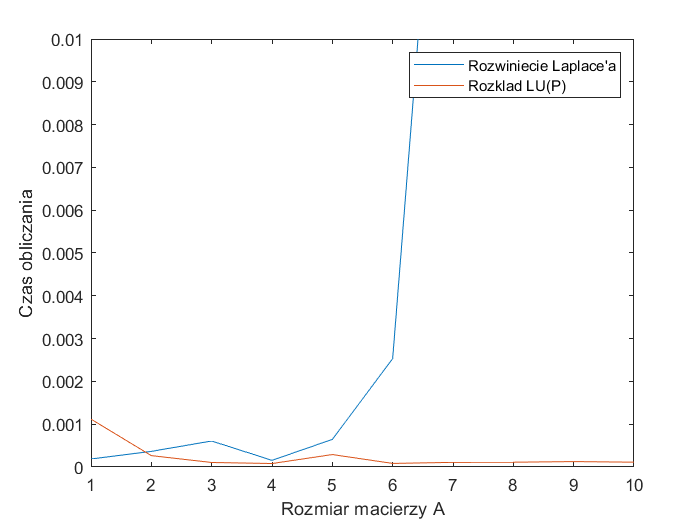

iterations=10;
tRozwiniecieLaplacea=zeros(1,iterations);
tDetLUP=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[detA]=RozwiniecieLaplacea(A);
tRozwiniecieLaplacea(i)=toc;

tic
[detA]=detLUP(A);
tDetLUP(i)=toc;
end

plot(x,tRozwiniecieLaplacea);
hold on;
plot(x,tDetLUP);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("Rozwiniecie Laplace'a","Rozklad LU(P)")
ylim([0,0.01]);
hold off;

    b)

inverse_LU(A)

A=rand(3)*10;
[L,U]=gauss(A);
invMATLAB=inv(A)

invMATLAB =     0.1783    0.1376   -0.2161
    0.0053   -0.2794    0.3372
   -0.0310    0.5402   -0.4330


invInverse_LU=inverse_LU(A)

invInverse_LU =     0.1783    0.1376   -0.2161
    0.0053   -0.2794    0.3372
   -0.0310    0.5402   -0.4330


inverse_LU2(A)

A=rand(3)*10;
invMATLAB=inv(A)

invMATLAB =     0.2262   -0.0087   -0.6553
   -0.5641    0.4197    0.8735
    0.0531   -0.1305    0.6612


invInverse_LU2=inverse_LU2(A)

invInverse_LU2 =     0.2262   -0.0087   -0.6553
   -0.5641    0.4197    0.8735
    0.0531   -0.1305    0.6612


porownanieSzybkosci

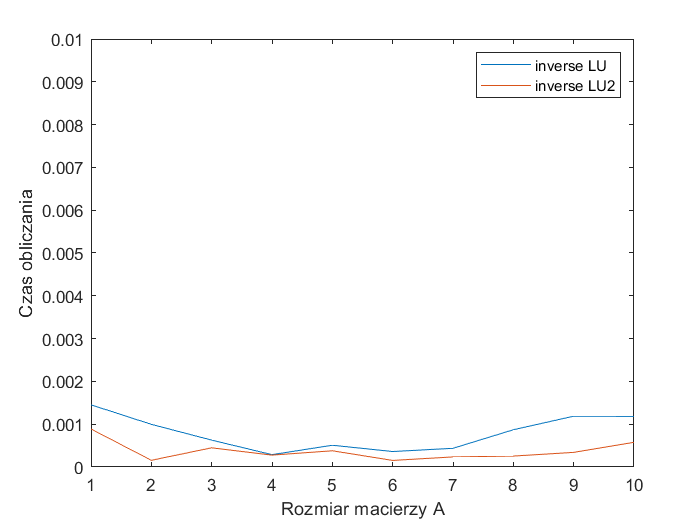

iterations=10;
tInverse_LU=zeros(1,iterations);
tInverse_LU2=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[invA]=inverse_LU(A);
tInverse_LU(i)=toc;

tic
[invA]=inverse_LU2(A);
tInverse_LU2(i)=toc;
end

plot(x,tInverse_LU);
hold on;
plot(x,tInverse_LU2);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("inverse LU","inverse LU2")
ylim([0,0.01]);
hold off;